# Analyze Car Peformance Mode

## Open the Simulink file

open("CarMode_start.slx");

## Design the logic flow

Below pseudocode describes the logic for choosing a driving mode.

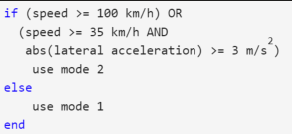

### Step 1 - Add the Abs block

The Signal Editor block provides a source of simulated data. The block's first port outputs speed, and the second port outputs lateral acceleration.

You must first preprocess the input data. In particular, you must find the absolute value of lateral acceleration, so that the model treats left and right turns the same way.

**Task**

Add an **Abs (Simulink > Math Operations)** block to take the absolute value of lateral acceleration

### Step 2 - Add Compare to Constant block

**Task**

Add **three** **Compare to Constant** blocks to the model. Set their conditions to

- ***>= 100***

- ***>= 35***

- ***>= 3***

Connect the blocks to their appropriate signals (e.g. >= 3 is related to acceleration). Remember you can branch any signal by using the right mouse button to click and drag.

### Step 3 - Add Logical Operator block

**Task**

Add a **Logical Operator** block to the model. Use the default Operator value, AND. Connect the appropriate **Compare to Constant** blocks to create the statement: 

*speed >= 35 km/h*** AND ***abs(lateral acceleration) >= 3 m/s2*

### Step 4 - Add second Logical Operator block

**Task**

Add a second **Logical Operator** block to the model. Change its Operator to OR. 

Connect the blocks to create the statement: 

*(speed >= 100 km/h***) OR ***(speed >= 35 km/h*** AND ***abs(lateral acceleration) >= 3 m/s2)*

### Step 5 - Add the Switch block and the Constant block

The final step is to add the logical statement, described here:

**if** (speed >= 100 km/h) **OR** 

 (speed >= 35 km/h **AND** abs(lateral acceleration) >= 3 m/s2)

    use mode 2

**else**

    use mode 1

**end**

**Task**

Add a **Switch** block to the model and connect the output from the previous task to the control signal. 

Add two **Constant** blocks, with values 1 and 2, to represent the driving modes. 

Connect the blocks to the appropriate locations on the Switch block.

### Step 6 - Add the scope block and run the simulation

**Task**

Connect the output of the OR Logical Operator block to the Scope block 

Connect / Branch the output of **speed** and** lateral_acceleration signal** to the Scope block

Run the Simulation

- Click on the **Run** button 

- Open the ***Scope*** to observe the system response

## Analysis

Observe the effect of the Car Performance Mode on scope.

- Add the legend in the scope (Scope --> Settings --> Legend)

- Set the Display Grid to 3 by 1 (Scope --> Display Grid)